Comp Apps Final Project - Risk Analysis of Coronary Artery Disease 

by: CardioNet 

Load data

Heart_Data = readtable("Cleveland_Heart_Data.xlsx");

Extract Data

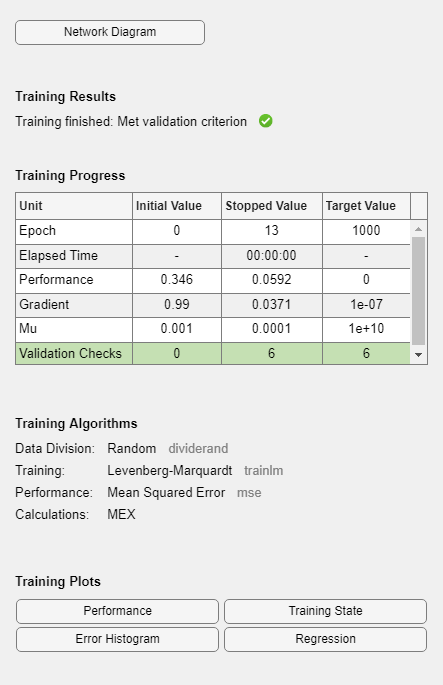

Age = Heart_Data(:,1);
Sex = Heart_Data(:,2);
Chest_Pain = Heart_Data(:,3);
Rest_BP = Heart_Data(:,4);
Cholesterol = Heart_Data(:,6); 
Fasting_BS = Heart_Data(:,5);
Max_HR = Heart_Data(:,8);
ExInd_Agnia = Heart_Data(:,9);
Thal = Heart_Data(:,13);
Disease = Heart_Data(:,14);

%Normalize features
features = table2array([Age, Sex, Chest_Pain, Rest_BP, Cholesterol, Fasting_BS, Max_HR, ExInd_Agnia, Thal]);
features = mapminmax(features)';

% Neural Network Training
net = feedforwardnet([10 5]);
net.trainFcn = 'trainlm'; % Levenberg-Marquardt backpropagation
net.trainParam.showWindow = true;
targets = table2array(Disease)';
[net, tr] = train(net, features, targets);


% Specify Division of Data
net.divideParam.trainRatio = 0.7;
net.divideParam.valRatio = 0.15;
net.divideParam.testRatio = 0.15;

% View the trained network
view(net);

% Display information about the first and second layers
net.layers{1}

ans =     Neural Network Layer
 
              name: 'Hidden 1'
        dimensions: 10
       distanceFcn: (none)
     distanceParam: (none)
         distances: []
           initFcn: 'initnw'
       netInputFcn: 'netsum'
     netInputParam: (none)
         positions: []
             range: [10x2 double]
              size: 10
       

net.layers{2}

ans =     Neural Network Layer
 
              name: 'Hidden 2'
        dimensions: 5
       distanceFcn: (none)
     distanceParam: (none)
         distances: []
           initFcn: 'initnw'
       netInputFcn: 'netsum'
     netInputParam: (none)
         positions: []
             range: [5x2 double]
              size: 5
       


% Display the learned weights and biases
LWeights = net.LW

LWeights = 3×3 cell array
    {0×0  double}    {0×0 double                           }    {0×0 double}
    {5×10 double}    {0×0 double                           }    {0×0 double}
    {0×0  double}    {[0.3757 0.8479 0.8309 -0.7263 0.8407]}    {0×0 double}


biases = net.b

biases = 3×1 cell array
    {10×1 double}
    { 5×1 double}
    {[  -0.8839]}
